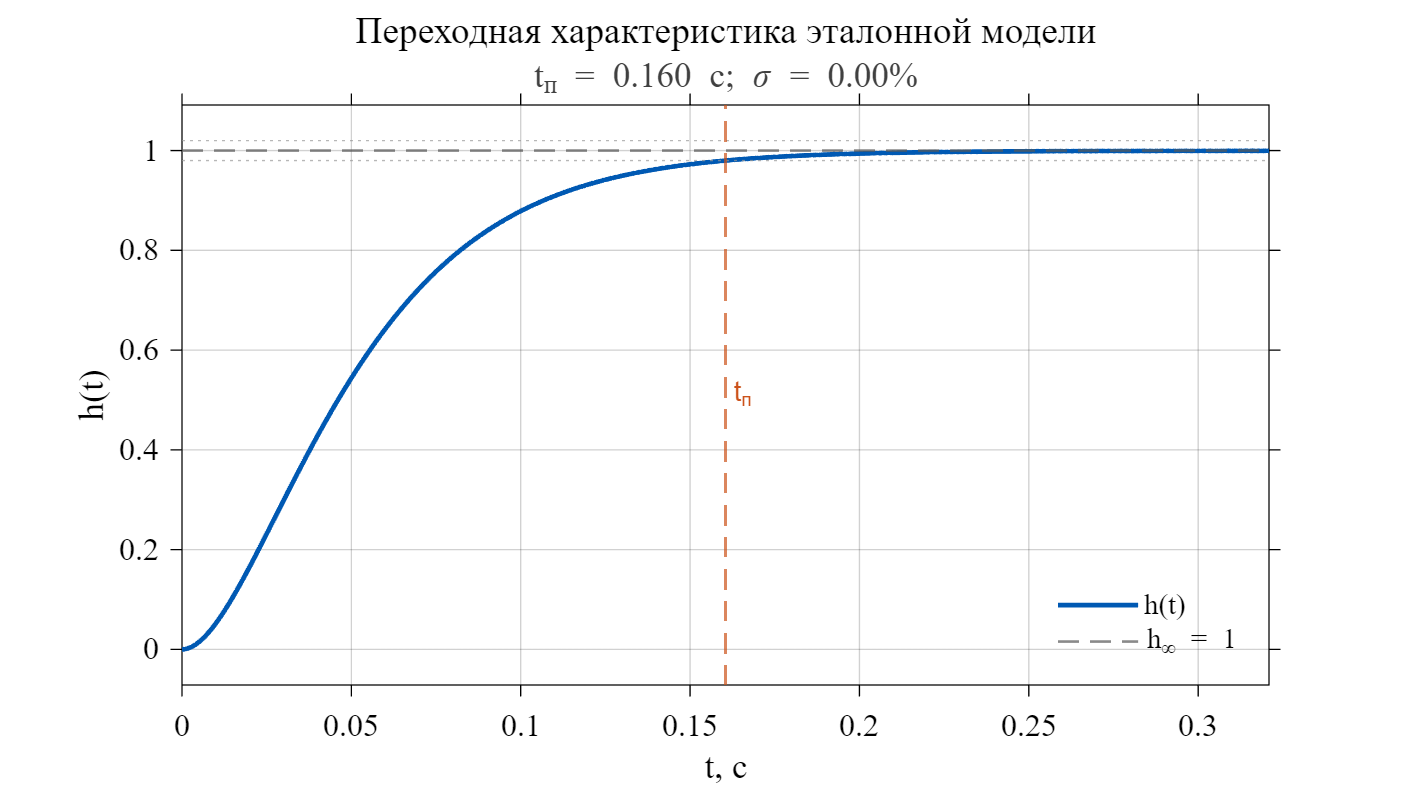

A_M = [0 1; -1329.9240 -72.9240];
B_M = [0; 1329.4782];
b_M = B_M;
out = sim('ystep');
y_st = out.y_step;
save(fullfile(fileparts(get_param('ystep', 'FileName')), 'ystep.mat'), 'y_step');

t = y_st.Time;
y = y_st.Data;
t0 = str2double(get_param('ystep/Step', 'Time'));
idx = t >= t0;
t = t(idx) - t0;
y = y(idx);

settlingBand = 0.02;
S = stepinfo(y, t, 1, 'SettlingTimeThreshold', settlingBand);

fig = figure('Color', 'white', 'Position', [100 100 1000 560]);
plot(t, y, 'LineWidth', 1.8, 'Color', [0 0.35 0.70]);
hold on;
yline(1, '--', 'Color', [0.35 0.35 0.35], 'LineWidth', 1);
yline([1-settlingBand 1+settlingBand], ':', ...
    'Color', [0.60 0.60 0.60], 'HandleVisibility', 'off');
xline(S.SettlingTime, '--', 't_{п}', 'Color', [0.80 0.32 0.10], ...
    'LineWidth', 1.1, 'LabelOrientation', 'horizontal', ...
    'LabelVerticalAlignment', 'middle', 'HandleVisibility', 'off');
set(gca, 'Color', 'white', 'FontName', 'Times New Roman', ...
    'FontSize', 12, 'XColor', 'black', 'YColor', 'black', ...
    'GridAlpha', 0.18, 'TickDir', 'out');
grid on;
box on;
xlim([0 min(t(end), 2*S.SettlingTime)]);
ylim('padded');
xlabel('t, с', 'Color', 'black');
ylabel('h(t)', 'Color', 'black');
title('Переходная характеристика эталонной модели', ...
    'FontSize', 14, 'FontWeight', 'normal', 'Color', 'black');
subtitle(sprintf('t_{п} = %.3f с; \\sigma = %.2f%%', ...
    S.SettlingTime, S.Overshoot), ...
    'Interpreter', 'tex', 'Color', [0.25 0.25 0.25]);
legend('h(t)', 'h_{\infty} = 1', 'Location', 'southeast', ...
    'Box', 'off', 'TextColor', 'black', 'Color', 'white');

imagePath = fullfile(fileparts(get_param('ystep', 'FileName')), ...
    '..', 'tex', 'images', 'reference_step.png');
exportgraphics(fig, imagePath, 'Resolution', 300, 'BackgroundColor', 'white');

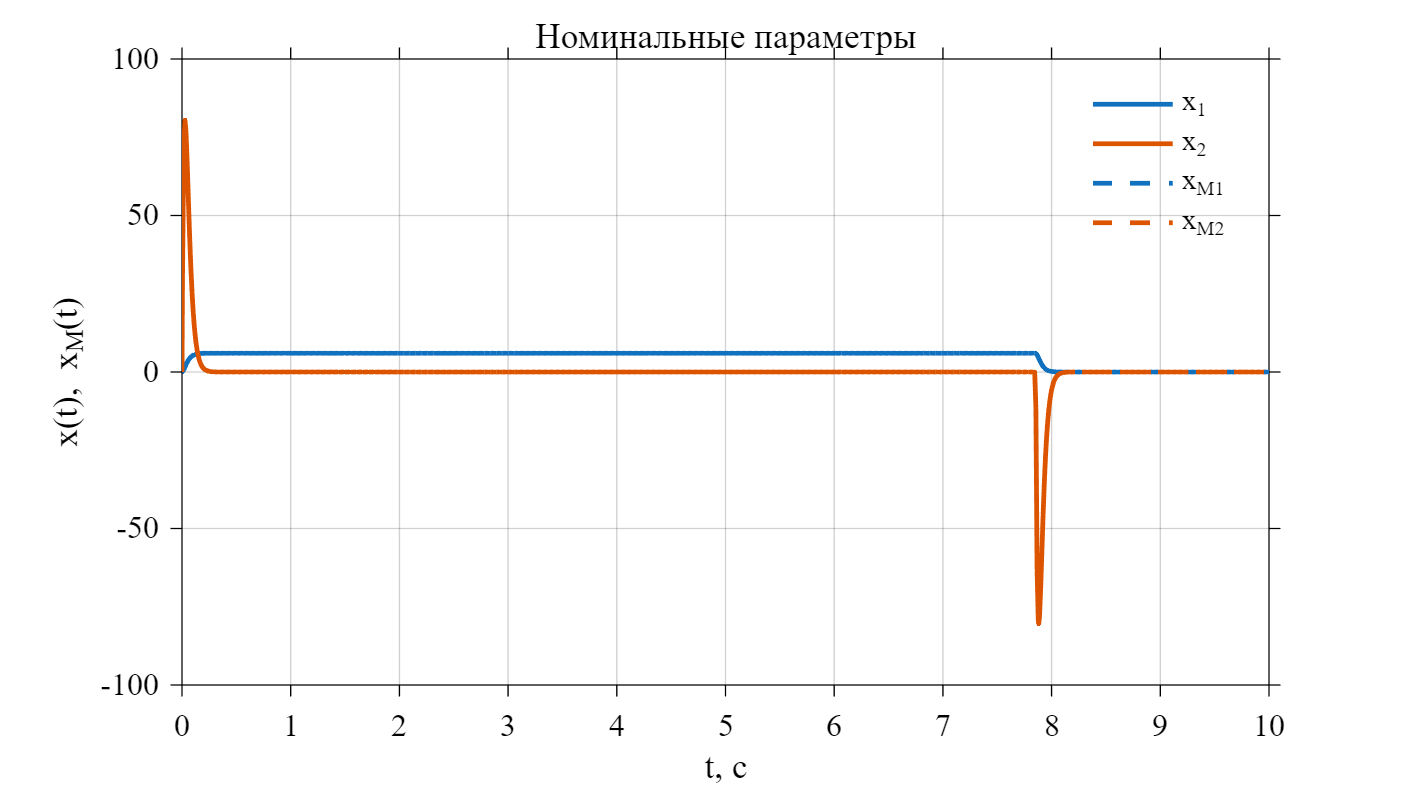

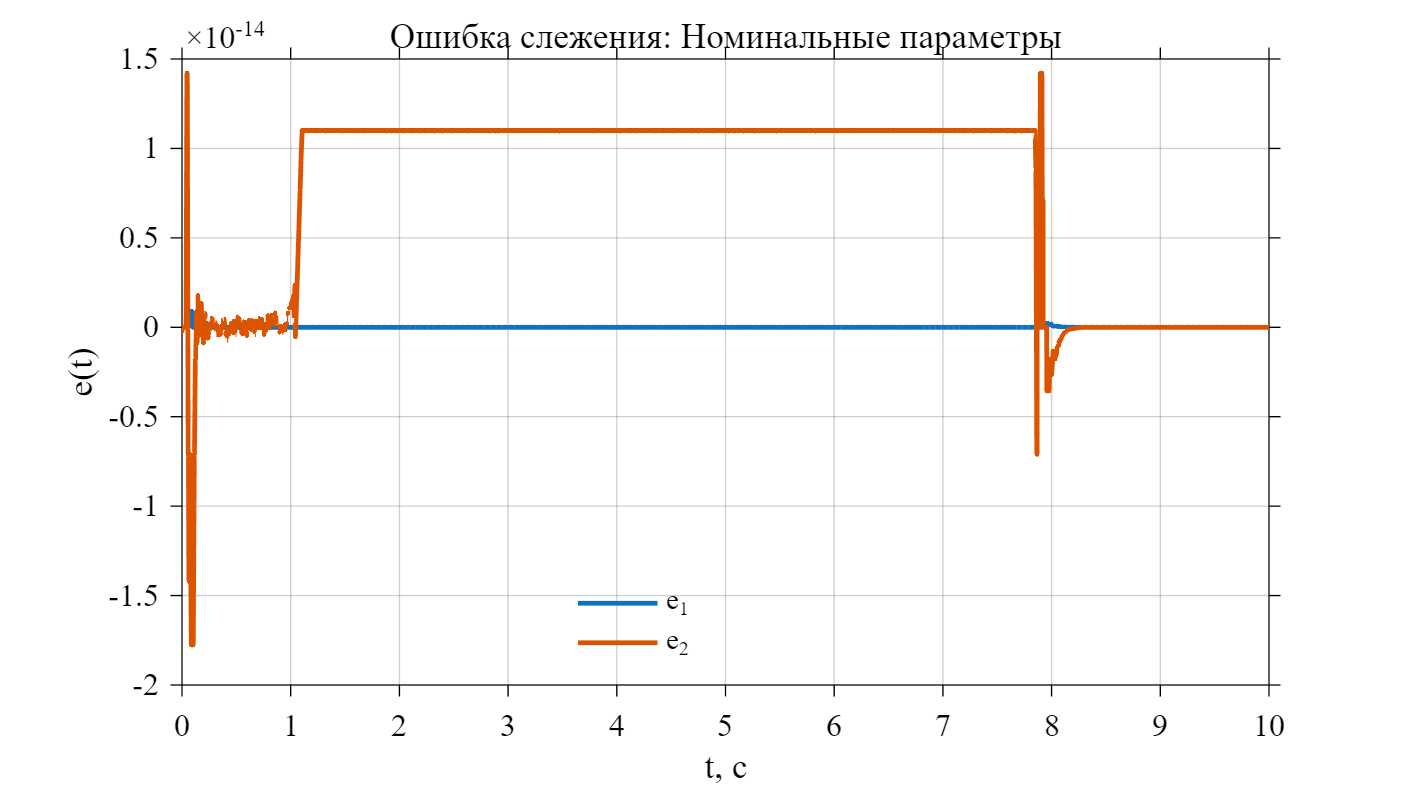

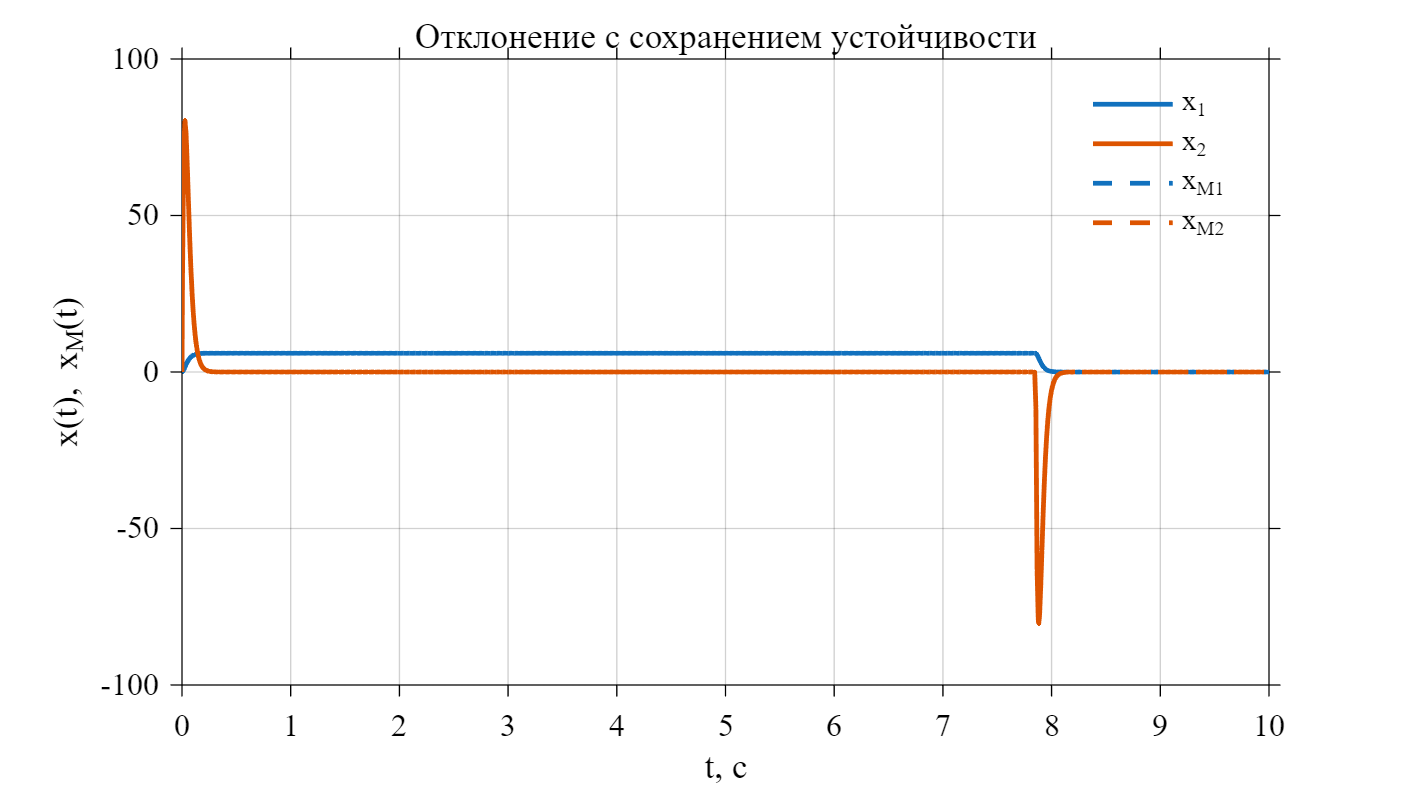

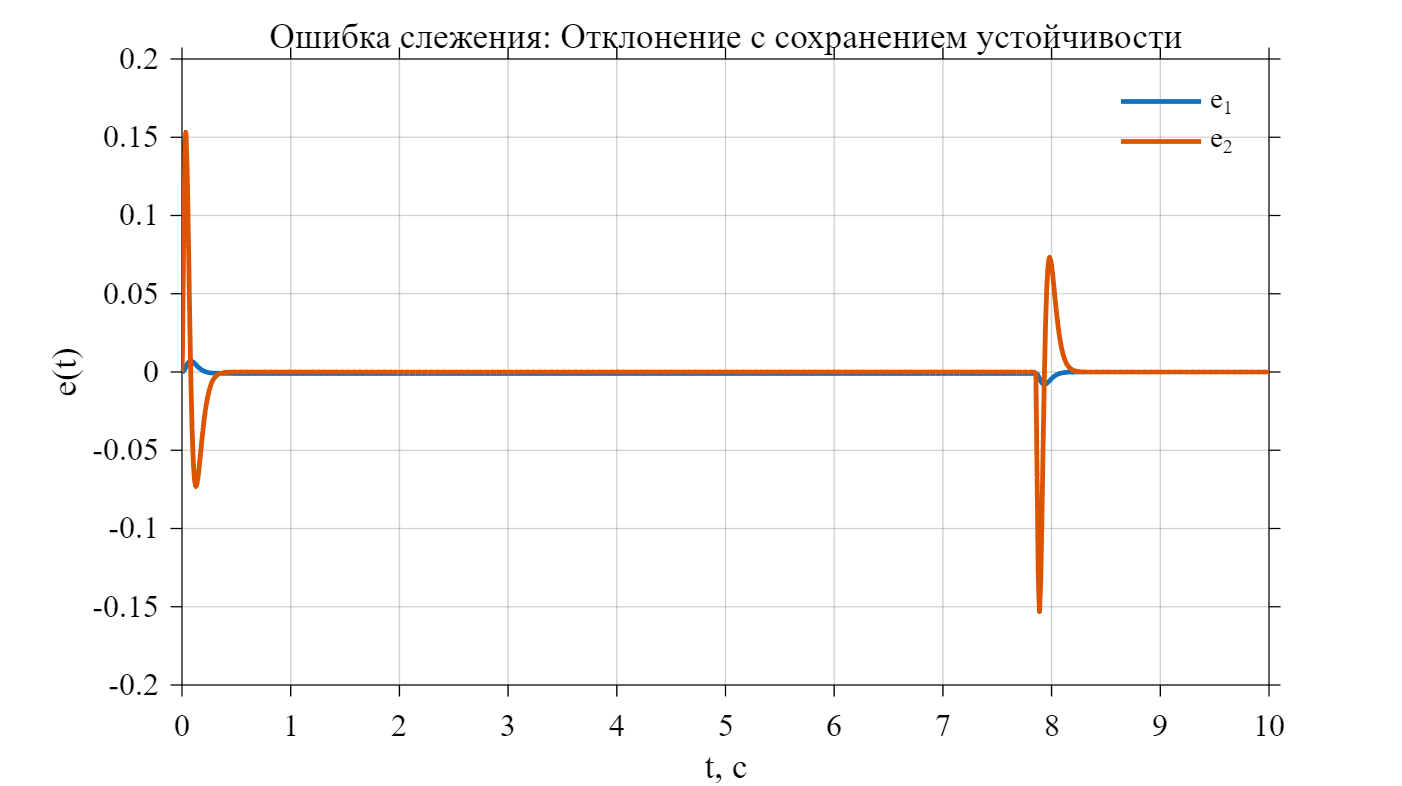

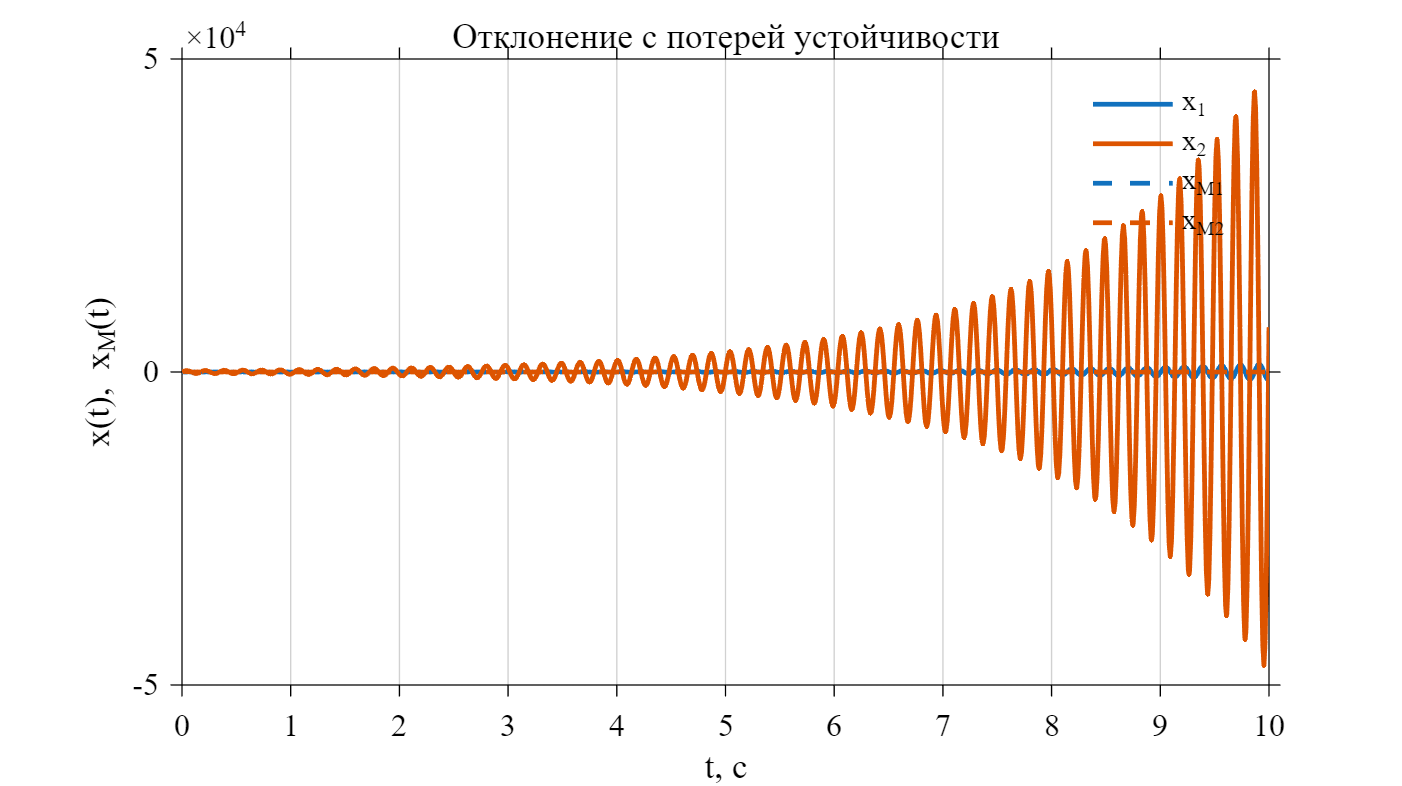

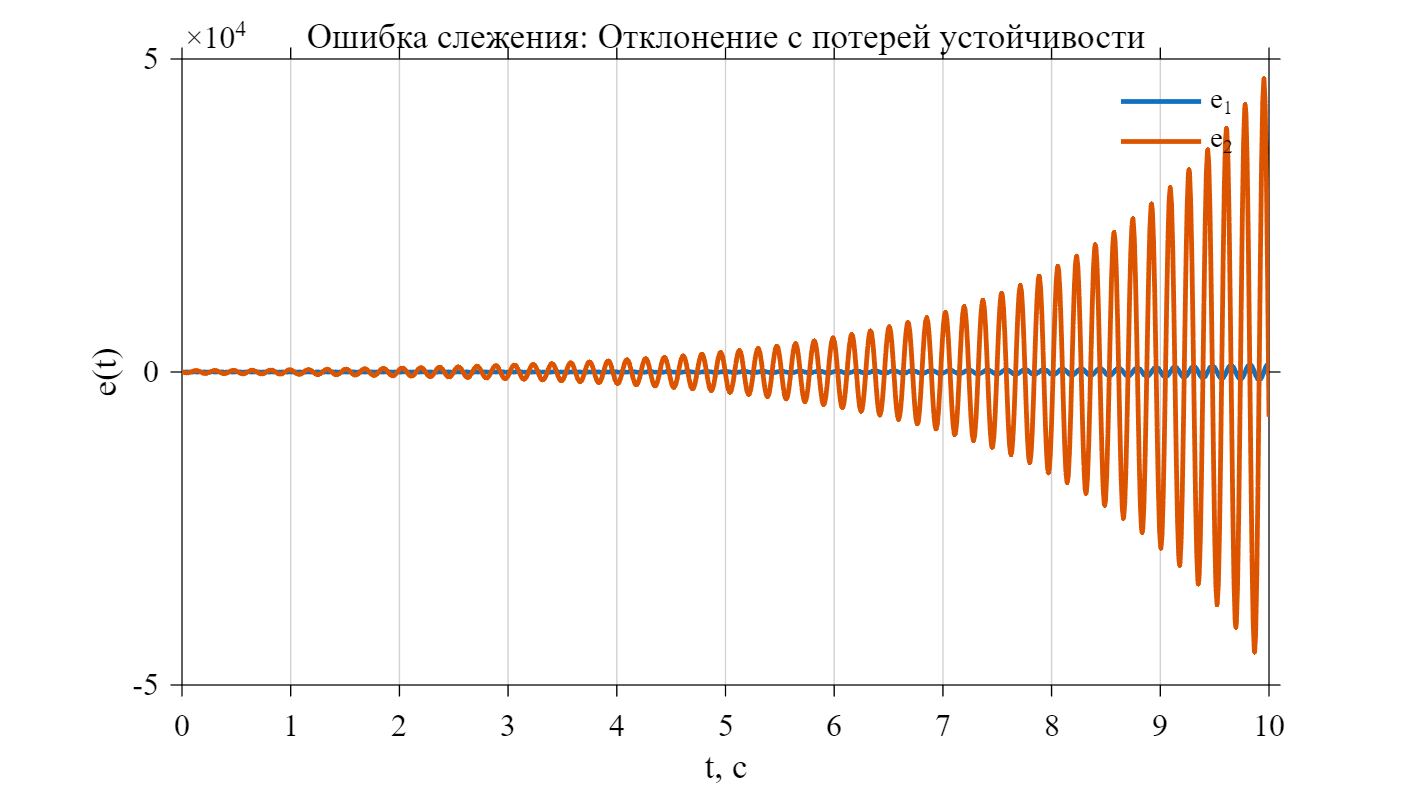

A_M = [0 1; -1329.4782 -72.9240];
b_M = [0; 1329.4782];
b = [0; 1];

a0 = [-1 -1.2 -1];
a1 = [-1 -0.8 -75];

names = {'nominal', 'stable', 'unstable'};
titles = {'Номинальные параметры', ...
    'Отклонение с сохранением устойчивости', ...
    'Отклонение с потерей устойчивости'};

for k = 1:3
    A = [0 1; -a0(k) -a1(k)];
    out = sim('y2');

    t = out.y.Time;
    x = out.y.Data;
    x_M = out.y_M.Data;
    e = x_M - x;

    codeFolder = fileparts(get_param('y2', 'FileName'));
    fileBase = ['nonadaptive_' names{k}];
    save(fullfile(codeFolder, [fileBase '.mat']), ...
        't', 'x', 'x_M', 'e', 'A');

    fig1 = figure('Color', 'white', 'Position', [100 100 1000 560]);
    ax1 = axes(fig1);
    colororder(ax1, [0 0.35 0.70; 0.85 0.33 0.10]);
    plot(ax1, t, x, 'LineWidth', 1.8);
    hold(ax1, 'on');
    ax1.ColorOrderIndex = 1;
    plot(ax1, t, x_M, '--', 'LineWidth', 1.8);
    xlabel(ax1, 't, с', 'Color', 'black');
    ylabel(ax1, 'x(t), x_M(t)', 'Color', 'black');
    title(ax1, titles{k}, 'FontWeight', 'normal', 'Color', 'black');
    legend(ax1, 'x_1', 'x_2', 'x_{M1}', 'x_{M2}', ...
        'Location', 'best', 'Box', 'off', ...
        'TextColor', 'black', 'Color', 'white');

    fig2 = figure('Color', 'white', 'Position', [150 150 1000 560]);
    ax2 = axes(fig2);
    colororder(ax2, [0 0.35 0.70; 0.85 0.33 0.10]);
    plot(ax2, t, e, 'LineWidth', 1.8);
    xlabel(ax2, 't, с', 'Color', 'black');
    ylabel(ax2, 'e(t)', 'Color', 'black');
    title(ax2, ['Ошибка слежения: ' titles{k}], ...
        'FontWeight', 'normal', 'Color', 'black');
    legend(ax2, 'e_1', 'e_2', 'Location', 'best', ...
        'Box', 'off', 'TextColor', 'black', 'Color', 'white');

    set([ax1 ax2], 'Color', 'white', ...
        'FontName', 'Times New Roman', 'FontSize', 12, ...
        'XColor', 'black', 'YColor', 'black', ...
        'XGrid', 'on', 'YGrid', 'on', 'GridAlpha', 0.18, ...
        'Box', 'on', 'TickDir', 'out', 'XLim', [t(1) t(end)]);

    exportgraphics(fig1, ...
        fullfile(codeFolder, '..', 'tex', 'images', [fileBase '.png']), ...
        'Resolution', 300, 'BackgroundColor', 'white');
    exportgraphics(fig2, ...
        fullfile(codeFolder, '..', 'tex', 'images', [fileBase '_error.png']), ...
        'Resolution', 300, 'BackgroundColor', 'white');
end